%addpath 'iwave\development\matlab'

load_parameters

t_end = 0.01; % secs

load('rmss_3.mat')
Qs = logspace(5, 7, 5);
Ts = linspace(10e-3, 50e-3, 5);
taus = logspace(log10(0.5e-5), log10(2e-4), 8);

L_Qs = length(Qs);
L_Ts = length(Ts);

avg_rmss = mean(rmss, 1);
std_rmss = std(rmss, 1);
avg_std = mean(std_rmss, 'all')

avg_std = 62.2350


avg_lins_rms = mean(linspace_rms, 1);

best_taus = zeros(L_Qs, L_Ts);

for j = 1 : L_Qs
    Q_orig = Qs(j);
    lins_rms = avg_lins_rms(1, j);
    
    for k = 1 : L_Ts
        T = Ts(k);
        
        [min_rms, min_index] = min(rmss(1,j,k,:));
        min_rms;
        best_taus(j, k) = taus(min_index);
        
        for m = 1 : size(rmss, 4)
            %tau = taus(m)
            %avg_rmss(1, j, k, m)
        end
    end
end

best_taus

best_taus = 	1.0e+-3 *

    0.2000    0.2000    0.2000    0.2000    0.2000
    0.1181    0.2000    0.2000    0.2000    0.2000
    0.0143    0.0143    0.0143    0.0143    0.0143
    0.0143    0.0243    0.0243    0.0243    0.0243
    0.0697    0.0697    0.0697    0.0697    0.0697


reps = 5

reps = 5


best_rmss = zeros(reps, L_Ts, L_Ts);

parfor l = 1 : reps
    f_axion = generate_axion_frequency_maxwellian(t, f_sampling, t_coherence, f_a, axion_linewidth);
    signal = generate_axion_signal(t, f_sampling, f_axion, axion_power_over_Q);
    noise = generate_thermal_noise(t);
    
    for j = 1 : L_Qs
        Q_orig = Qs(j)
        Q = Q_orig / heterodyning_ratio;
        
        bandwidth = f_a / Q; % or f_a_original / Q_orig
        limiting_band = [f_a-bandwidth, f_a+bandwidth];
        
        %linspace_gives_rms = rms(f_axion - linspace(limiting_band(1), limiting_band(2), length(t)));
        %linspace_rms(l, j) = linspace_gives_rms;
        
        signal_Qed = signal * sqrt(Q_orig);
        
        for k = 1 : L_Ts % par here
            T = Ts(k)
            
            noise_power = calculate_noise_power(f_sampling, T);
            noise_Ted = noise * sqrt(noise_power);
            
            tau_iwave = best_taus(j, k);
            f_guess = f_a;
    
            STATE_PS = iwave_setup(f_sampling, tau_iwave, f_guess, 0);
            state_res = resonator_setup();
            f_iwave = zeros(size(t));
            %ys = zeros(size(t));
            %xs = zeros(size(t));
            f_0_current = f_a + bandwidth/4; % starting guess
            
            for i = 1 : length(t)
                x = signal_Qed(i) + noise_Ted(i);
                x = x * sqrt(R(Q_orig, f_axion(i) - f_0_current, f_0_current + heterodyning_shift));
                [state_res, y] = resonator_step2(state_res, x, f_0_current, bandwidth, f_sampling);
                [STATE_PS, pdout, pqout, paout, peout, pfout, pfstateout] = iwave_step(STATE_PS, y);
                f_0_current = pfout;
                if f_0_current > limiting_band(2)
                    f_0_current = limiting_band(2);
                elseif f_0_current < limiting_band(1)
                    f_0_current = limiting_band(1);
                end
                f_iwave(i) = f_0_current;
                %ys(i) = y;
                %xs(i) = x;
            end
    
            % front to chop off
            start_secs = 0.0015;
            assert(start_secs < t(end)/3);
            start = round(start_secs * f_sampling);
            the_rms = rms(f_iwave(start:end) - f_axion(start:end))
            best_rmss(l, j, k) = the_rms;
            
            %figure
            %plot(t, f_axion - f_a)
            %hold on
            %plot(t, f_iwave - f_a)
        end
    end
end

num = L_Qs * L_Ts;
Q_for_plot = zeros(1, num);
T_for_plot = zeros(1, num);
rms_for_plot = zeros(1, num);

best_rms_mean = mean(best_rmss, 1);

count = 0;
 
for j = 1 : L_Qs
    Q = Qs(j)
    
    for k = 1 : L_Ts
        count = count + 1;
        
        T = Ts(k);
        r = best_rms_mean(1, j, k);
        
        Q_for_plot(count) = Q;
        T_for_plot(count) = T;
        rms_for_plot(count) = r;
    end
end

Q = 100000

Q = 3.1623e+05

Q = 1000000

Q = 3.1623e+06

Q = 10000000

adstyle(8, 8)
%scatter(T_for_plot, Q_for_plot, 500, log(log(rms_for_plot)), 'filled')
scatter(T_for_plot*1e3, Q_for_plot, 100000./log10(rms_for_plot).^5, rms_for_plot, 'filled')
%scatter(T_for_plot, Q_for_plot, 200000./rms_for_plot, rms_for_plot, 'filled')
set(gca, 'yscale','log', 'colorscale','log')
axis('padded')
c = colorbar('Ticks', [5e2 1e3 2e3 4e3]);
ylabel(c, 'RMS (Hz)')

map = [1*linspace(0, 1, 500).^.3' 0.38*linspace(0, 1, 500).^.3' (1 - linspace(0, 0.2, 500).^.3)']

map =          0         0    1.0000
    0.1551    0.0589    0.9043
    0.1909    0.0726    0.8822
    0.2156    0.0819    0.8669
    0.2351    0.0893    0.8550
    0.2513    0.0955    0.8449
    0.2655    0.1009    0.8362
    0.2780    0.1057    0.8284
    0.2894    0.1100    0.8214
    0.2998    0.1139    0.8150


map(end,:)

ans =     1.0000    0.3800    0.3830


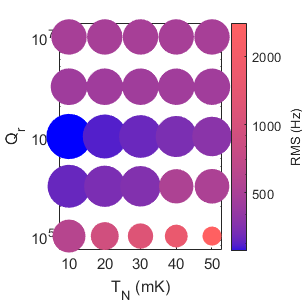


% colorbar - need to find where there is no match - ie if you draw a line
% right through the middle, and that should be the end of the color scale

colormap(map)
box('on')
xlabel('T_N (mK)')
ylabel('Q_r')

%saveas(gca, 'figures/quality_of_lock.eps', 'epsc');